clear
load('fmridata.mat');
whos

  Name               Size            Bytes  Class     Attributes

  Left_cIFS        256x1              2048  double              
  Left_iPCS        256x1              2048  double              
  Left_pAud        256x1              2048  double              
  Left_pVis        256x1              2048  double              
  Left_sPCS        256x1              2048  double              
  Left_tgPCS       256x1              2048  double              
  Right_cIFS       256x1              2048  double              
  Right_iPCS       256x1              2048  double              
  Right_pAud       256x1              2048  double              
  Right_pVis       256x1              2048  double              
  Right_sPCS       256x1              2048  double              
  Right_tgPCS      256x1              2048  double              
  braindata        256x12            24576  double              
  names              1x12             1576  cell                
  uncleandata      256x1

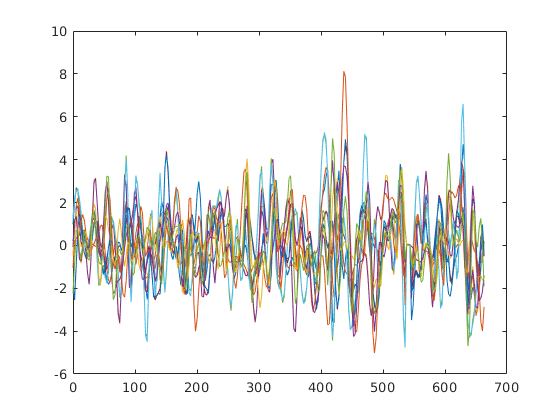

time = 0:2.6:255*2.6;
plot(time, braindata)

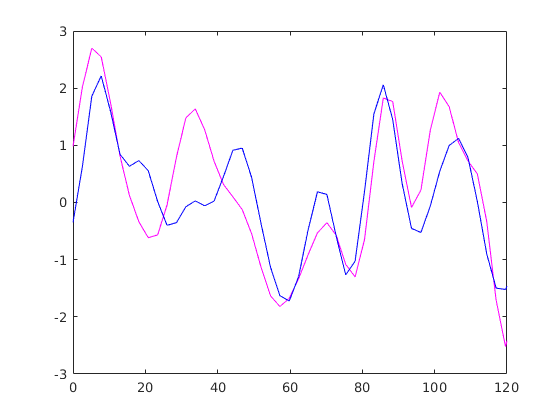

clf
plot(time, Left_pAud, 'm-', time, Right_pAud, 'b-')
xlim([0 120])

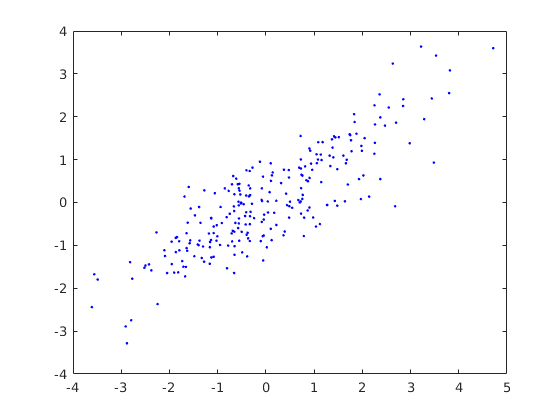

clf
% plot correlation
plot(Left_pAud, Right_pAud, 'b.')

corr(Left_pAud, Right_pAud)

ans = 0.8495

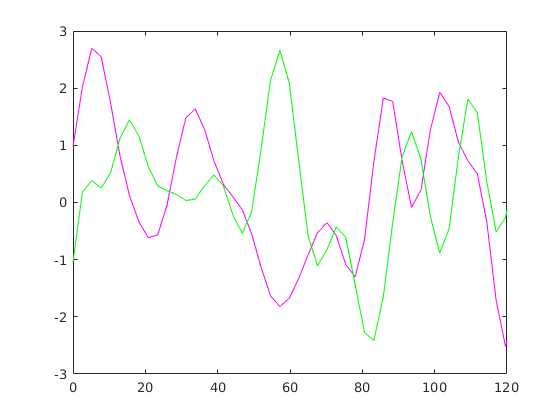

clf
plot(time, Left_pAud, 'm-', time, Left_sPCS, 'g-')
xlim([0 120])

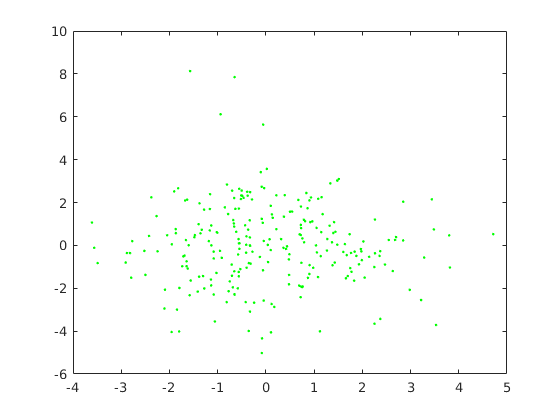

clf
% plot correlation
plot(Left_pAud, Left_sPCS, 'g.')

corr(Left_pAud, Left_sPCS)

ans = -0.0360

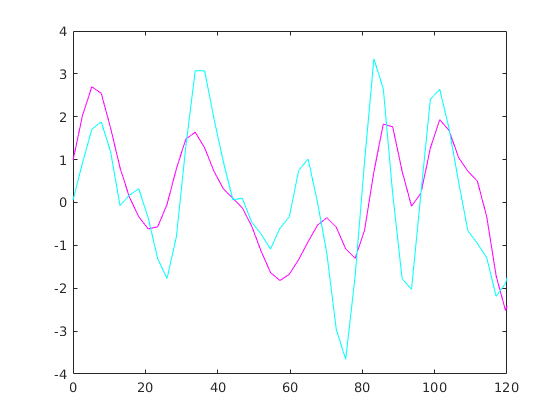

clf
plot(time, Left_pAud, 'm-', time, Left_tgPCS, 'c-')
xlim([0 120])

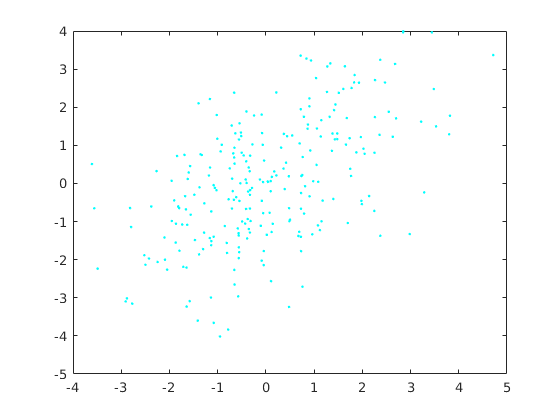

clf
% plot correlation
plot(Left_pAud, Left_tgPCS, 'c.')

corr(Left_pAud, Left_tgPCS)

ans = 0.5517

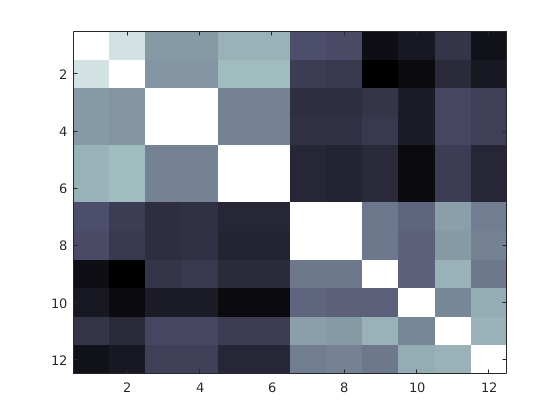

imagesc(corr(braindata))
colormap(bone)